计算沿着贴片阵列HIS表面的表面波的色散曲线

创建者：FTT

创建时间：2024.12.12

clear
clc
close all

HIS参数

D = 2e-3; %栅格周期
w = 0.2e-3; %条带宽度
d = 1e-3; %基板厚度
epsr = 10.2; %基板介电常数

常量

eps0 = 8.854*1e-12;
mu0 = 4*pi*1e-7;
c0 = 1/sqrt(eps0*mu0);
eta0 = sqrt(mu0/eps0);
ktlength = 1200; %kt假设点的个数
tor = 100; %容差

扫频范围

f = linspace(0, 20e9, 1000);
omega = 2*pi*f;
k0 = omega/c0; %真空波数
DispersionTM = zeros(ktlength, 2);
DispersionTE = zeros(ktlength, 2);

扫频

for i =1:length(omega)
kt = linspace(k0(i),1200,ktlength);
theta = acos(sqrt(k0(i).^2-kt.^2)/k0(i));

中间量

epseff = (epsr+1)/2; %等效均匀介电常数
keff = k0(i)*sqrt(epseff); %等效介质中的波数
etaeff = eta0/sqrt(epseff); %等效介质中的波阻抗
alpha = keff*D/pi*log(1/sin(pi*w/2/D)); %栅格常数
k = k0(i)*sqrt(epsr); %基板中的波数
beta = sqrt(k.^2 - kt.^2); %基板中的法向传播常数
theta2 = asin(sin(theta)/sqrt(epsr)); %根据折射定律计算的角度，论文式（22）

输入阻抗

ZinpTM = 1i*omega(i).*mu0.*tan(beta.*d)./beta.*cos(theta2).^2./(1-2.*keff.*alpha.*tan(beta.*d)./beta.*cos(theta2).^2); %TM输入阻抗，论文式（20）
ZinpTE = 1i*omega(i).*mu0.*tan(beta*d)./beta./(1-2*keff.*alpha.*tan(beta.*d)./beta.*(1-2/(epsr+1).*sin(theta).^2)); %TM输入阻抗，论文式（23）

自由空间阻抗

Z0TM = eta0.*cos(theta); %TM极化自由空间波阻抗，论文式（13）
Z0TE = eta0./cos(theta); %TE极化自由空间波阻抗，论文式（12）

得到满足共振条件的kt

[TMerror, TMindex] = min(abs(imag(ZinpTM-Z0TM)));
[TEerror, TEindex] = min(abs(imag(ZinpTE-Z0TE)));

存储对应的kt和omega

if TMindex ~= length(kt) && TMerror < tor
    DispersionTM(i,:) = [kt(TMindex), omega(i)];
else
    DispersionTM(i,:) = [NaN, NaN]; %表示在波数范围内没有谐振的点
end
if TEindex ~= length(kt) && TEerror < tor
    DispersionTE(i,:) = [kt(TEindex), omega(i)];
else
    DispersionTE(i,:) = [NaN, NaN];
end

结束

end

绘图

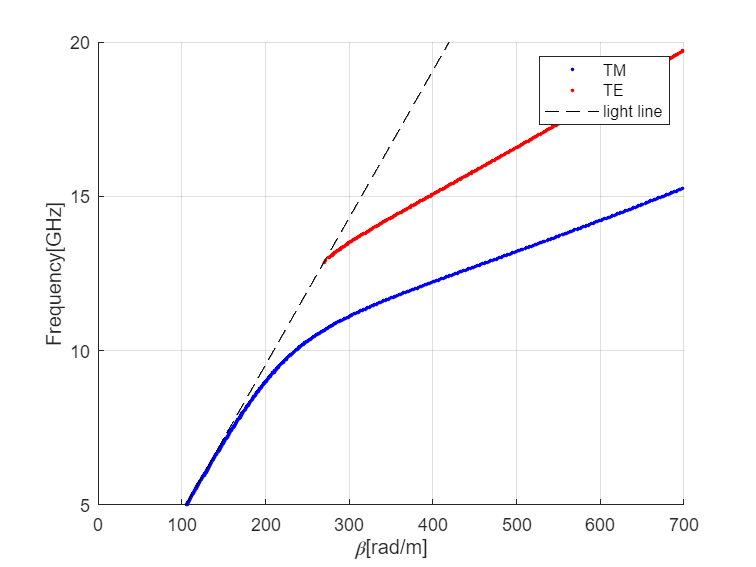

figure;
hold on
plot(DispersionTM(:, 1), DispersionTM(:, 2)/2/pi/1e9, 'b.')
plot(DispersionTE(:, 1), DispersionTE(:, 2)/2/pi/1e9, 'r.')
plot(k0, f/1e9, 'k--')
xlabel('\beta[rad/m]')
ylabel('Frequency[GHz]')
legend('TM','TE','light line')
xlim([0 700])
ylim([5 20])
grid on